# 10주차 과제 — 안정 여유

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — 여유를 읽고 표 채우기

- **2. 기본** (중간 · 40분 · 70점) — 사양을 만족하는 이득 고르기

- **3. 도전** (선택 · 가산점 10점) — 시간지연을 얼마까지 견디는가

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

clc; close all;
s = tf('s');

## 1. 몸풀기 — 여유를 읽어 표 채우기

**강의노트 3절을 그대로 보면 됩니다.**

강의노트에서 다룬 것과 **구조가 같고 숫자만 다른** 개루프입니다.


$$L(s) = \frac{K}{s\,(s+2)^2}$$


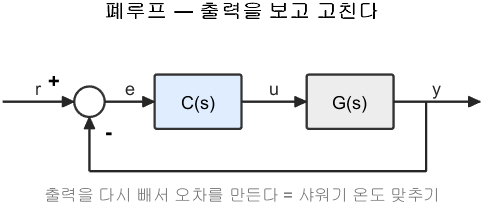

폐루프 — 출력을 보고 고친다

**그림 파일** `loop_closed.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_closed')`

읽는 순서를 다시 확인하십시오.

- 위상이 $-180^\circ$ 인 곳을 찾는다 $\rightarrow$ 거기서 **크기**를 읽으면 이득여유

- 크기가 $0$ dB 인 곳을 찾는다 $\rightarrow$ 거기서 **위상**을 읽으면 위상여유

G = 1/(s*(s+2)^2);

## 1-1. 표 채우기

`TODO` 한 줄만 채우면 됩니다.

fprintf('     K      GM[배]   GM[dB]    PM[도]     wcg      wcp\n');
fprintf('   ------  -------  -------  --------  -------  -------\n');
for K = [1 4 8 16 32]
    gm = NaN; pm = NaN; wcg = NaN; wcp = NaN;
    % TODO : [gm, pm, wcg, wcp] = margin(K*G);  로 바꾸십시오
    if isnan(gm)
        fprintf('   %6.1f  (아직 안 채움)\n', K);
        continue
    end
    fprintf('   %6.1f  %7.3f  %7.2f  %8.2f  %7.3f  %7.3f\n', ...
            K, gm, 20*log10(gm), pm, wcg, wcp);
end

## 1-2. 그림으로 확인

코드는 다 되어 있습니다. 표의 값이 그림에서 어디인지 찾아보십시오.

figure;
dg_margin(4*G, '이득여유와 위상여유 (K = 4)');

## 1-3. 답할 것 (두 문장이면 됩니다)

- 이 시스템의 **임계이득**(안정 한계가 되는 $K$)은 얼마입니까? 표에서 이득여유가 $1$ 배($0$ dB) 가 되는 곳을 찾으면 됩니다

- $K$ 를 두 배로 하면 이득여유는 몇 배가 됩니까? 왜 그렇습니까?

**스스로 확인하는 법** — 임계이득에서 `feedback(K*G,1)` 의 극점 실수부가 $0$ 이 되면 맞은 것입니다.

## 2. 기본 — 사양을 만족하는 이득 고르기

**강의노트 3절과 5절을 그대로 보면 됩니다.**

같은 플랜트에 사양이 주어졌습니다.

- 위상여유 $\ge 45^\circ$

- 이득여유 $\ge 6$ dB

- 오버슈트 $\le 25\%$

6~7주차에서 근궤적으로 하던 일을 오늘은 주파수영역에서 합니다. 도구는 `freq_scan` 입니다. `rl_scan` 의 주파수판이라고 보면 됩니다.

## 2-1. 1단계 : 이득을 훑는다

`freq_scan(C1, G, Kvec)` 의 `C1` 은 **이득을 뺀 제어기**입니다. 비례제어이므로 `1` 입니다. (7주차에서 배운 것과 같은 약속입니다.)

Kvec = logspace(-0.5, 1.8, 60);
T = freq_scan(1, G, Kvec);

ok = NaN;
% TODO : 아래 세 조건을 모두 만족하는 논리 배열을 만드십시오
%        ok = T.stable & T.PM >= 45 & T.GMdB >= 6 & T.OS <= 25;

fprintf('\n=== 2-1단계 : 사양을 만족하는 이득 ===\n');
if ~islogical(ok)
    fprintf('  ok 를 아직 안 채웠습니다.\n');
elseif any(ok)
    fprintf('  만족 범위 : K = %.2f ~ %.2f\n', min(T.K(ok)), max(T.K(ok)));
    sub = T(ok,:);
    fprintf('      K       PM[도]   GM[dB]   OS[%%]    ts[s]\n');
    fprintf('   --------  --------  -------  -------  -------\n');
    for i = round(linspace(1, height(sub), min(5,height(sub))))
        fprintf('   %8.3f  %8.2f  %7.2f  %7.2f  %7.2f\n', ...
                sub.K(i), sub.PM(i), sub.GMdB(i), sub.OS(i), sub.ts(i));
    end
else
    fprintf('  만족하는 K 가 없습니다. 사양을 다시 보십시오.\n');
end

## 2-2. 2단계 : 하나를 고르고 검증한다

만족 범위 안에서 **가장 큰 **$K$ 를 고르십시오. 왜 큰 쪽인가 — 이득이 클수록 외란을 잘 억제하고 정상상태 오차가 작기 때문입니다. (5주차에서 배운 대로입니다.)

K_pick = NaN;
% TODO : max(T.K(ok)) 로 고르십시오

if ~isnan(K_pick)
    Tcl = feedback(K_pick*G, 1);
    ii  = stepinfo(Tcl);
    [gm, pm] = margin(K_pick*G);

    fprintf('\n=== 2-2단계 : 검증 ===\n');
    fprintf('  K = %.3f\n', K_pick);
    fprintf('  위상여유 %.2f 도   (요구 45 이상)\n', pm);
    fprintf('  이득여유 %.2f dB   (요구 6 이상)\n', 20*log10(gm));
    fprintf('  오버슈트 %.2f %%    (요구 25 이하)\n', ii.Overshoot);
    fprintf('  정착시간 %.2f s\n', ii.SettlingTime);

    t = (0:0.02:12)';
    figure;
    subplot(1,2,1);
    plot(t, step(Tcl, t), 'LineWidth', 2); grid on; hold on;
    yline(1,'k--'); yline(1.25,'r:');
    xlabel('시간 [s]'); ylabel('출력');
    legend('출력','목표','오버슈트 한계','Location','southeast');
    title(sprintf('K = %.2f 검증', K_pick));
    subplot(1,2,2);
    margin(K_pick*G); grid on;
end

## 2-3. 답할 것 (세 문장이면 됩니다)

- 세 조건 중 **가장 먼저 걸리는** 것은 무엇입니까? (즉 $K$ 를 키울 때 제일 먼저 깨지는 것)

- 위상여유와 오버슈트 사이에 $\zeta \approx PM/100$ 관계가 얼마나 맞습니까?

- 만약 위상여유를 $60^\circ$ 로 올리라고 하면 $K$ 를 어떻게 해야 합니까? 그러면 무엇을 잃습니까?

## 3. 도전 (선택) — 시간지연을 얼마까지 견디는가

**강의노트 4-1절을 보면 됩니다.**

위상여유는 **견딜 수 있는 시간지연**으로 바꿔 읽을 수 있습니다.


$$\tau_{max} = \frac{PM\,[\mathrm{rad}]}{\omega_{cp}}$$


2번에서 고른 $K$ 에 대해 이 값을 구하고, 정말 그런지 확인하십시오.

if ~isnan(K_pick)
    [~, pm, ~, wcp] = margin(K_pick*G);
    tau_max = deg2rad(pm)/wcp;

    fprintf('\n=== 3. 견딜 수 있는 지연 ===\n');
    fprintf('  PM = %.2f 도, wcp = %.3f rad s^-1\n', pm, wcp);
    fprintf('  예상 한계 지연 tau_max = %.4f s\n\n', tau_max);

    fprintf('     tau[s]    PM[도]    폐루프 극점 실수부 최댓값\n');
    fprintf('   ---------  --------  ------------------------\n');
    for tau = [0, tau_max*0.5, tau_max*0.9, tau_max*1.1]
        Ld = K_pick*G*exp(-tau*s);
        [~, pmd] = margin(Ld);
        mx = max(real(pole(feedback(pade(Ld,6), 1))));
        fprintf('   %9.4f  %8.2f  %24.4f\n', tau, pmd, mx);
    end
end

## 3-1. 답할 것 (두 문장이면 됩니다)

- 예상한 한계 지연에서 실제로 극점이 허수축을 넘습니까?

- 견딜 수 있는 지연을 두 배로 늘리려면 무엇을 어떻게 해야 합니까? ($\tau_{max} = PM/\omega_{cp}$ 를 보고 생각해 보십시오)

## 4. 제출과 채점

제출할 것

- 이 파일의 `TODO` 를 채운 `.m`

- 그림 두 장 (1-2절의 여유 그림, 2-2절의 검증 그림)

- 답할 것에 대한 짧은 서술 (한 문단이면 충분합니다)

채점 기준

- **1번 30점** — 표가 채워져 있고 임계이득을 맞게 찾았는가

- **2번 70점** — 만족 범위를 찾고 고른 $K$ 를 검증했는가

- **3번 +10점** — 한계 지연을 구하고 확인했는가 (선택)

감점 항목 (세 개뿐입니다)

- `margin` 에 **폐루프**를 넣은 경우 (개루프를 넣어야 합니다)

- 이득여유를 배율과 dB 중 무엇으로 적었는지 밝히지 않은 경우

- 그림에 축 이름이나 단위가 없는 경우